# Linear Control Design II - Group Work Problem Module 11 

## Description

This group work module deals with the design of a full state feedback controller for the model of the aircraft analysed in Group Work Module 5 (the SISO model).

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =       -0.0558      -0.9968       0.0802       0.0415
        0.598       -0.115      -0.0318            0
        -3.05        0.388       -0.465            0
            0       0.0805            1            0


B = [0.00729; -0.475; 0.153; 0]

B =       0.00729
       -0.475
        0.153
            0


C = [0 1 0 0]

C =      0     1     0     0


D = 0;

**Problem 1**

Transform the continuous time model given in Module 5 into the controller canonical form.

% Your solution goes here:
chP = charpoly(A);
a = chP(end:-1:2);
sz = size(A,1);
P = zeros(sz);
for i = 1:sz
    if i == 1
        P(:,sz-i+1) = B;
    else
        P(:,sz-i+1) = A*P(:,sz-i+2)+chP(i)*P(:,sz);
    end
end
p1 = B;p2 = A*p1+chP(2)*p1;p3 = A*p2+chP(3)*p1; p4 = A*p3+chP(4)*p1;
P_cc = [p4 p3 p2 p1];
% Confirmation of loop results
P_equiv = ~sum(sum(round(P,10)~=round(P_cc,10)))

P_equiv = logical
   1


A_cc = round(P\A*P,10),B_cc = P\B,C_cc = C*P, D_cc = D,

A_cc =             0            1            0            0
            0            0            1            0
            0            0            0            1
   -0.0036741     -0.51163     -0.93887      -0.6358


B_cc =      0
     0
     0
     1


C_cc =     -0.056326     -0.11871     -0.24789       -0.475


D_cc =      0


**Problem 2**

It is desired to assign the eigenvalues through state feedback such that the damping ratio for the least damped eigenvalues is increased to approximately 0.7, and such that natural frequencies and time constants are approximately unchanged. A reasonable assignment could be:


$$\lambda = \left\{\matrix{-0.01 \cr -0.6 \cr -0.5\pm0.5j} \right.$$


Find the gain matrix K for the controller


$$u = -\textbf{Kx}+r$$


by applying the method from Section 4.3.1 in the textbook. Check that the eigenvalues of the closed-loop system have been assigned as desired.

% Your solution goes here:
[wn zeta po] = damp(A);damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -3.29e-02 + 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -3.29e-02 - 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -5.63e-01                 1.00e+00       5.63e-01          1.78e+00    
 -7.28e-03                 1.00e+00       7.28e-03          1.37e+02    


realPoles = po(imag(po)==0);realPoles_new = [-0.6 -0.01]';
timeConst = -1./realPoles; timeConst_new = -1./realPoles_new;
disp('Real Poles'),...
disp('    Old Poles    New Poles'),disp([realPoles realPoles_new]),...
disp('      Old Tau      New Tau'),disp([timeConst timeConst_new]),...

complexPoles = po(imag(po)~=0); complexPoles_new = [-0.5-0.5j -0.5+0.5j]';...
wn_old = wn(imag(po)~=0);wn_new = abs(complexPoles_new);...
zeta_old = zeta(imag(po)~=0); zeta_new = -real(complexPoles_new)./wn_new;...
disp('Complex Poles'),...
disp('      Old Poles                  New Poles'),disp([complexPoles complexPoles_new]),...
disp('       Old wn       New wn'),disp([wn_old wn_new]),...
disp('   Old zeta       New zeta'),disp([zeta_old zeta_new]);

Real Poles


    Old Poles    New Poles
     -0.56265         -0.6
    -0.007278        -0.01



      Old Tau      New Tau
       1.7773       1.6667
        137.4          100



Complex Poles


      Old Poles                  New Poles
    -0.032935 +    0.94665i         -0.5 +        0.5i
    -0.032935 -    0.94665i         -0.5 -        0.5i



       Old wn       New wn
      0.94723      0.70711
      0.94723      0.70711



   Old zeta       New zeta
      0.03477      0.70711
      0.03477      0.70711



chP_alpha = poly([realPoles_new;complexPoles_new]);
alpha = chP_alpha(end:-1:2);
Kcc = alpha-a

Kcc =   -0.00067415     -0.20063      0.17713       0.9742


K = Kcc/P

K =       -0.5869      -1.9909      0.21453     0.086175


damp(A-B*K)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.00e-02                 1.00e+00       1.00e-02          1.00e+02    
 -5.00e-01 + 5.00e-01i     7.07e-01       7.07e-01          2.00e+00    
 -5.00e-01 - 5.00e-01i     7.07e-01       7.07e-01          2.00e+00    
 -6.00e-01                 1.00e+00       6.00e-01          1.67e+00    


**Problem 3**

Add the controller to the Simulink open-loop model and carry out a simulation with the function shown on Figure 1 as input to the closed-loop system. Plot the states, the output and the rudder angle.

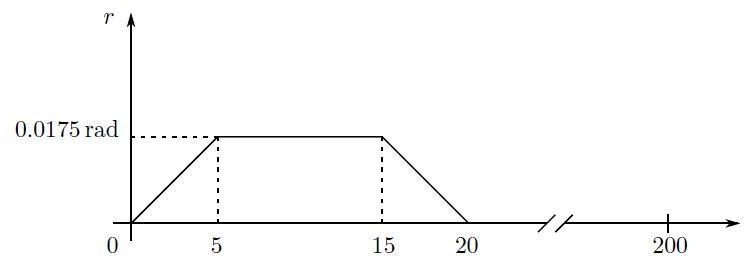


$$Figure\,1: Input\,signal\,to\,the\,closed\,loop\,system.$$


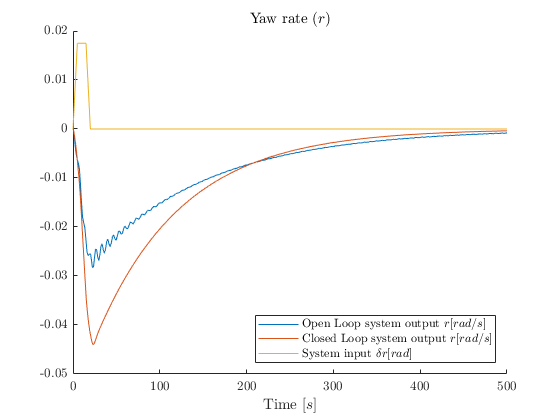

% Your solution goes here:
A_mdl = A;
B_mdl = B;
C_mdl = C;
D_mdl = D;
K_mdl = K;
simSwitch = -1;

t = 0:0.1:200;
U1 = t(1:50)*0.0175/5;
U2 = t(51:150)*0+0.0175;
U3 = 0.0175-U1;
U4 = t(201:end)*0;
Us = [U1 U2 U3 U4];
inp = [t' Us'];

T_end = 500;
figure
sim('Mdl_11_OpenLoop.slx',T_end,[],inp)
hold on
plot(tout,yout.signals.values)
sim('Mdl_11_CloseLoop_Continuous.slx',T_end,[],inp)
plot(tout,yout.signals.values),xlabel('Time $[s]$')
plot([t T_end],[Us 0])
legend('Open Loop system output $r [rad/s]$','Closed Loop system output $r [rad/s]$',...
    'System input $\delta r [rad]$','Location','southeast')
title('Yaw rate $(r)$')

**Problem 4**

Repeat Problems 2 and 3 with the largest time constant decreased by a factor 50 and by applying Ackermann's formula (the Matlab's function is called *acker()*). The Ackermann's formula has to be applied to the original model.

% Your solution goes here:
[val,ind] = max(timeConst_new);
taus = timeConst_new; taus(ind) = val/50;
newPoles = -1./taus;
po_new = [newPoles;complexPoles_new];


$$\tau =\frac{1}{p}\to p=\frac{1}{\tau }$$


K_cont = acker(A,B,po_new)

K_cont =       0.44744       -3.048     0.086022     0.016254


damp(A-B*K_cont)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -5.00e-01 + 5.00e-01i     7.07e-01       7.07e-01          2.00e+00    
 -5.00e-01 - 5.00e-01i     7.07e-01       7.07e-01          2.00e+00    
 -5.00e-01                 1.00e+00       5.00e-01          2.00e+00    
 -6.00e-01                 1.00e+00       6.00e-01          1.67e+00    


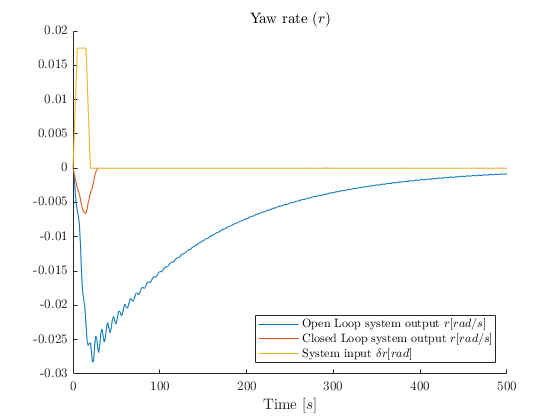

K_mdl = K_cont;
figure
sim('Mdl_11_OpenLoop.slx',T_end,[],inp)
hold on
plot(tout,yout.signals.values)
sim('Mdl_11_CloseLoop_Continuous.slx',T_end,[],inp)
plot(tout,yout.signals.values),xlabel('Time $[s]$')
plot([t T_end],[Us 0])
legend('Open Loop system output $r [rad/s]$','Closed Loop system output $r [rad/s]$',...
    'System input $\delta r [rad]$','Location','southeast')
title('Yaw rate $(r)$')

**Problem 5**

Repeat Problem 4 for a discrete time controller. Do not forget to convert the eigenvalues to the discrete domain. The discrete time controller must be tested together with the continuous time plant. To enable interaction between the continuous and discrete time parts of the control loop do not forget to insert digital-to-analogue (DAC) and analogue-to-digital (ADC) converters into the system. The DAC is usually a zero-order hold, and such a block is available in Simulink's discrete library. The ADC is implemented in Simulink as a discrete transfer function (same library) with 1 as numerator and denominator, as shown in Figure 2. All discrete blocks use the parameter *Sample Time*, which has to be chosen in a suitable manner.

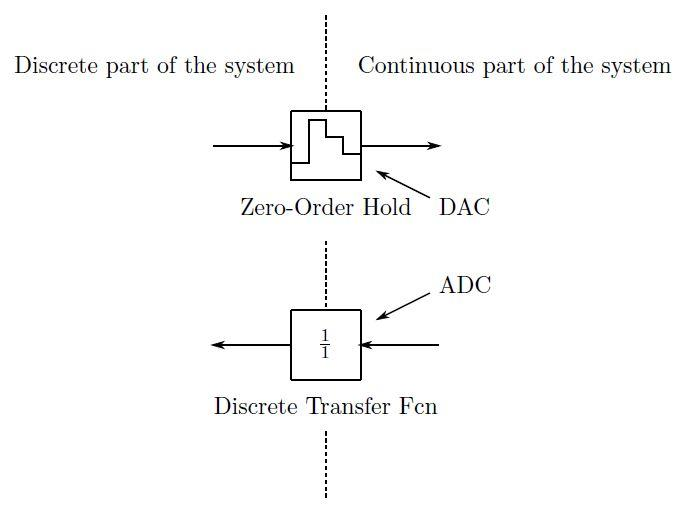


$$Figure\,2:Simulink\,discretization\,blocks.$$


% Your solution goes here:
min(taus)/10

ans =       0.16667


% Choose a sampling time
Ts = 0.1;
sys_cont = ss(A,B,C,D);
sys_disc = c2d(sys_cont,Ts);
discPoles = exp(po_new*Ts)

discPoles =       0.94176 +          0i
      0.95123 +          0i
      0.95004 +   0.047542i
      0.95004 -   0.047542i


K_disc = acker(sys_disc.A,sys_disc.B,discPoles)

K_disc =       0.31547      -2.8363     0.085049     0.015931


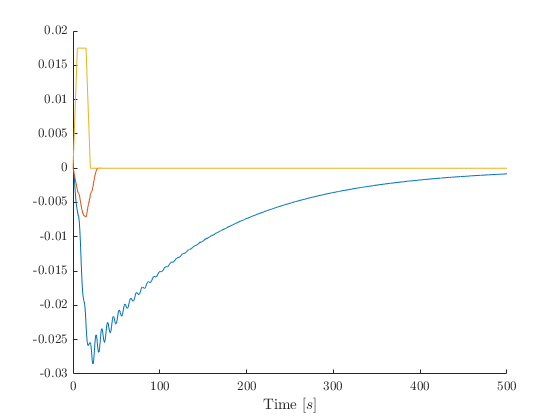

K_mdl = K_disc;
sim('Mdl_11_CloseLoop_Discrete.slx',T_end,[],inp)

tin = 0:Ts:T_end;
Us0 = [Us tin(length(Us)+1:end)*0];
% Simulate Discrete Open Loop System
[y0, t0, ~] = lsim(sys_disc,Us0',tin',[0 0 0 0]');
figure
hold on
% Simulate Continuous system w/ Discrete Controller
plot(t0,y0)
plot(tout,yout.signals.values),xlabel('Time $[s]$')
plot([t T_end],[Us 0])

**Problem 6**

Compare the system responses from Problem 4 and 5, and discuss the effect of discretization on the system performance.

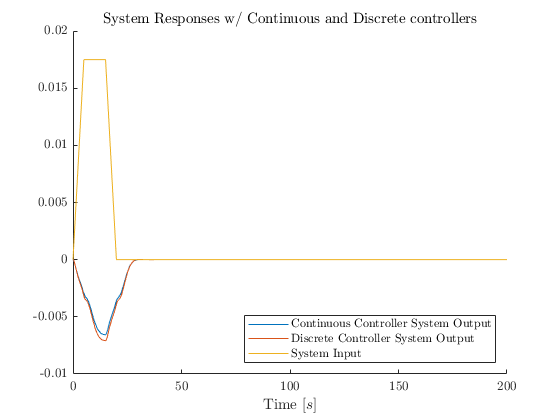

% Your solution goes here:
T_end = 200;
K_mdl = K_cont;
sim('Mdl_11_CloseLoop_Continuous',T_end,[],inp)

figure
hold on
plot(tout,yout.signals.values)

K_mdl = K_disc;
sim('Mdl_11_CloseLoop_Discrete.slx',T_end,[],inp)

plot(tout,yout.signals.values),xlabel('Time $[s]$')
plot(inp(:,1),inp(:,2)),legend('Continuous Controller System Output',...
    'Discrete Controller System Output', 'System Input','Location','southeast')
title('System Responses w/ Continuous and Discrete controllers')

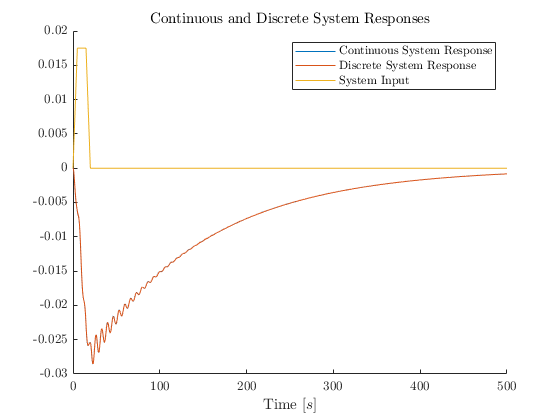

figure
[yc, tc, ~] = lsim(sys_cont,Us0',tin',[0 0 0 0]');
[yd, td, ~] = lsim(sys_disc,Us0',tin',[0 0 0 0]');
figure
hold on
plot(tc,yc)
plot(td,yd),xlabel('Time $[s]$')
plot(tin,Us0),legend('Continuous System Response',...
    'Discrete System Response', 'System Input')
title('Continuous and Discrete System Responses')